clc;
clear;
close all;

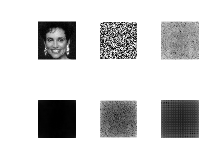

% imagen del rectangulo
Ic = zeros(500,500);
Ic(:,:)=0;
Ic(225:275,245:255)=255;

% 1 imagen original
Img = imread("FigP0402(a)(woman).tif");

% 2 angulo de fase
fft = fft2(Img);
sfft = fftshift(fft);
angulofase = angle(fft);

% 3 reconstruccion usando la fase del angulo
H = exp(1j*angulofase);
H_conv_F = conv2(H,abs(fft),'same');
Img_rec_ang = ifft2(H_conv_F);

% 4 reconstruccion usando el espectro
Img_rec_spec = ifft2(abs(fft));

% 5 reconstruccion con el angulo de fase de la imagen original
% y el espectro de la imagen del rectangulo
f_r = abs(fft2(Ic));
H_conv_fr = conv2(H,f_r,'same');
Img_rec_wr = ifft2(H_conv_fr);

% 6 reconstruccion con el angulo de fase de la imagen del rectangulo
% y el espectro de la imagen original
angulofaseR = angle(f_r);
HR = exp(1j*angulofaseR);
%convolucion de H 
HR_conv_F = conv2(HR,abs(fft),'same');
Img_rec_wHR = ifft2(HR_conv_F);

figure
subplot(2,3,1)
imshow(Img,[]);
subplot(2,3,2)
imshow(real(angulofase),[]);
subplot(2,3,3)
imshow(log(abs(Img_rec_ang)+0.03),[]);
subplot(2,3,4)
imshow(abs(Img_rec_spec),[]);
subplot(2,3,5)
imshow(abs(log(Img_rec_wr+1)),[]);
subplot(2,3,6)
imshow(abs(log(Img_rec_wHR)),[]);

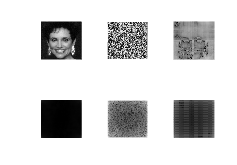

% imagen del rectangulo
Ic = zeros(500,500);
Ic(:,:)=0;
Ic(225:275,245:255)=255;

% 1 imagen original
Img = imread("FigP0402(a)(woman).tif");

% 2 angulo de fase
fft = fft2(Img);
sfft = fftshift(fft);
angulofase = angle(fft);

% 3 reconstruccion usando la fase del angulo
H = exp(1j*angulofase);
H_conv_F = conv2(ifft2(H),ifft2(abs(fft)),'same');
%Img_rec_ang = ifft2(H_conv_F);

% 4 reconstruccion usando el espectro
Img_rec_spec = ifft2(abs(fft));

% 5 reconstruccion con el angulo de fase de la imagen original
% y el espectro de la imagen del rectangulo
f_r = abs(fft2(Ic));
H_conv_fr = conv2(H,f_r,'same');
Img_rec_wr = ifft2(H_conv_fr);

% 6 reconstruccion con el angulo de fase de la imagen del rectangulo
% y el espectro de la imagen original
angulofaseR = angle(f_r);
HR = exp(1j*angulofaseR);
%convolucion de H 
HR_conv_F = conv2(HR,abs(fft),'same');
Img_rec_wHR = ifft2(HR_conv_F);

figure
subplot(2,3,1)
imshow(Img,[]);
subplot(2,3,2)
imshow(real(angulofase),[]);
subplot(2,3,3)
imshow(abs(log(fftshift(H_conv_F))),[]);
subplot(2,3,4)
imshow(abs(Img_rec_spec),[]);
subplot(2,3,5)
imshow(abs(log(Img_rec_wr+1)),[]);
subplot(2,3,6)
imshow(abs(log(Img_rec_wHR)),[]);